rob = MyRobot();

Failed to open the port!
Reconnect Robot!
Unrecognized function or variable 'lib_name'.



x = linspace(0,0.4,20);
y = linspace(0,0.4,20);
z = linspace(0,0.4,20);
cords_list = [0,0,0];
fail_counter = 0;
for i=1:length(x)
    for ii = 1:length(y)
        for iii = 1:length(z)
            try
                rob.move_c(x(i),y(ii),z(iii),0);
                cords_list = [cords_list;x(i),y(ii),z(iii)];
            end
        end
    end
end

[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed 


rob.disable_motors()

[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!


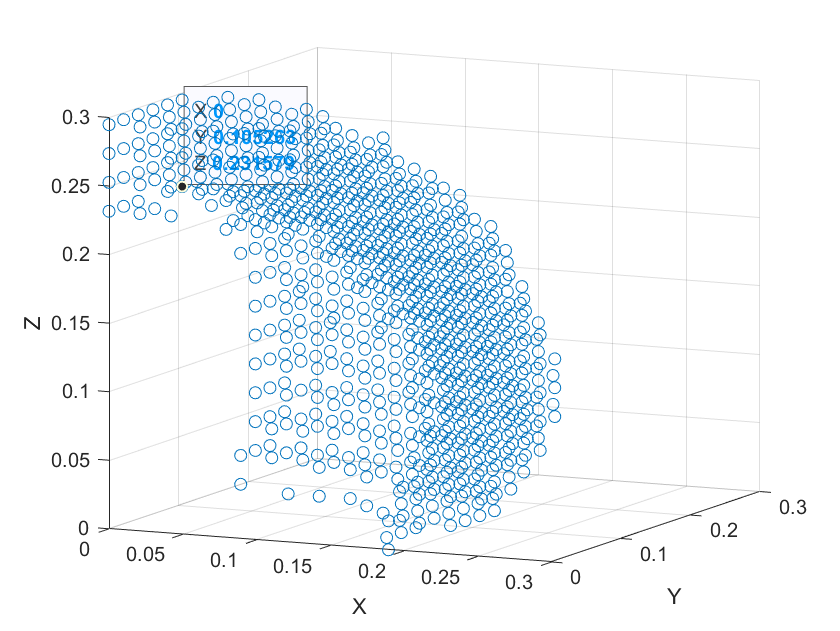

cords_list = cords_list(2:end,:);
scatter3(cords_list(:,1),cords_list(:,2),cords_list(:,3));
xlabel("X");
ylabel("Y");
zlabel("Z");

x_min = min(cords_list(:,1));
x_max = max(cords_list(:,1));

y_min = min(cords_list(:,2));
y_max = max(cords_list(:,2));

z_min = min(cords_list(:,3));
z_max = max(cords_list(:,3));

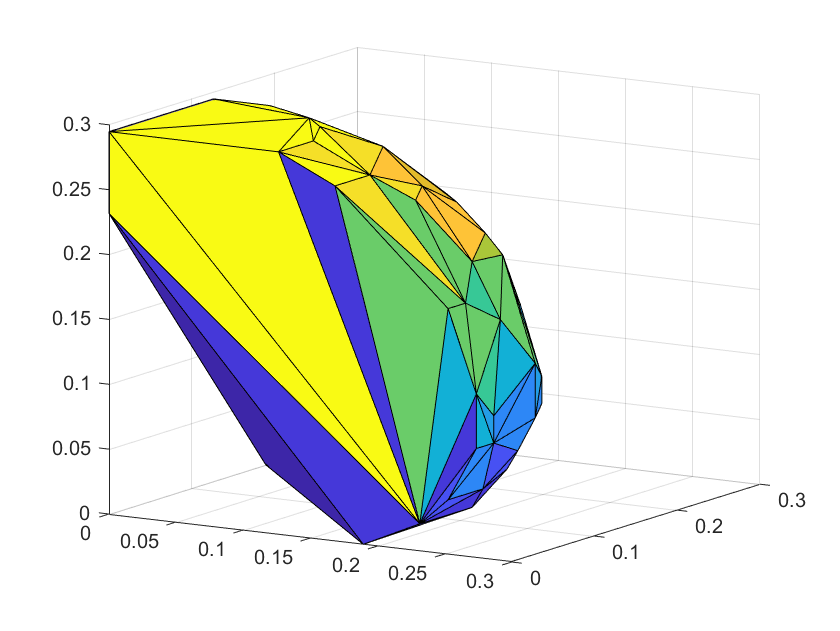

conv_hull = convhulln(cords_list);
trisurf(conv_hull,cords_list(:,1),cords_list(:,2),cords_list(:,3))

rob = MyRobot();

Failed to open the port!
Reconnect Robot!
Unrecognized function or variable 'lib_name'.


rob.dh = [0   	-pi/2	0.0955 0;               % Denavit Hartenberg Parameters for Robot (a, alpha, d, theta)
            0.116	0       0       0;
            0.116	0	0	0;
            0.09611  	0	0	0];

x = linspace(0,0.43,40);
y = linspace(0,0.43,20);
z = linspace(0,0.43,20);
cords_list_l = [0,0,0];
for i=1:length(x)
    for ii = 1:length(y)
        for iii = 1:length(z)
            try
                rob.move_c(x(i),y(ii),z(iii),0);
                cords_list_l = [cords_list_l;x(i),y(ii),z(iii)];
            end
        end
    end
end

[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed 


rob.disable_motors()

[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!
[TxRxResult] Failed transmit instruction packet!


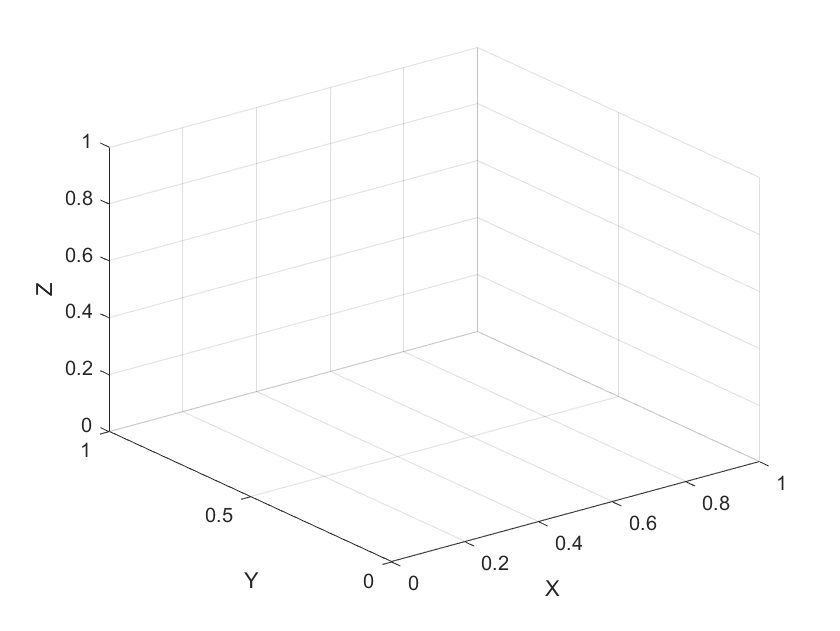

cords_list_l = cords_list_l(2:end,:);
scatter3(cords_list_l(:,1),cords_list_l(:,2),cords_list_l(:,3));
xlabel("X");
ylabel("Y");
zlabel("Z");